# Model Predictive Control for Humanoid Walking Generation

Copyright 2019 The MathWorks, Inc. 

Author: Carlos Santacruz-Rosero, PhD  - Application Engineering

## 3D-LIP Equations

A walking robot can be represented by a 3D Linear Inverted Pendulum:

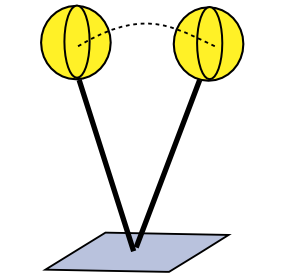                            

The equations of the 3D-LIP are:


$$\overset{\cdot \cdot }{x} =\frac{g}{z_c }\left(x-p_x \right)$$



$$\overset{\cdot \cdot }{y} =\frac{g}{z_c }\left(y-p_y \right)$$


Rewriting the equations to have the ZMP as the output:


$$p_x =x-\frac{z_c }{g}\text{ }\overset{\cdot \cdot }{x}$$


## Define constants for the 3D-LIP

g = 9.8;         % Gravity

g = 9.8000

zc = 0.18;       % Center of Mass Height (constant)

zc = 0.1800

Ts = 1e-2;       % Sample Time 

## Create state space representation for one axis

We are going to follow the approach proposed by Kajita[1] to design a pattern generator. First, we need to obtain a State-Space representation where the ZMP is the output, let's define the input u as the time derivate of the horizontal acceleration of the CoM


$$u_x \equiv \frac{d}{\mathrm{dt}}\overset{\cdot \cdot }{x}$$


We obtain the following dynamical system


$$\frac{d}{\mathrm{dt}}\left\lbrack \begin{array}{c}
x\\
\overset{\cdot }{x} \\
\overset{\cdot \cdot }{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1 & 0\\
0 & 0 & 1\\
0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\overset{\cdot }{x} \\
\overset{\cdot \cdot }{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack u_x$$



$$p_x =\left\lbrack \begin{array}{c}
1 & 0 & -\frac{z_c }{g}
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
x\\
\overset{\cdot }{x} \\
\overset{\cdot \cdot }{x} 
\end{array}\right\rbrack$$


Note that is the exact same equation for the "y" axis of motion. Let's do it in MATLAB now, 

% Define state space matrices
A = [0,1,0;0,0,1;0,0,0];
B = [0;0;1];
C = [1,0,-zc/g; 1,0,0; 0,1,0];      % zmp, pos, vel
D = [0;0;0];

% Create state space representation
lip_x = ss(A,B,C,D);
lip_y = ss(A,B,C,D);

% Specify names
lip_x.InputName = 'xddd';
lip_x.StateName = {'x', 'xd', 'xdd'};
lip_x.OutputName = {'px', 'x', 'xd'};
lip_y.InputName = 'yddd';
lip_y.StateName = {'y', 'yd', 'ydd'};
lip_y.OutputName = {'py', 'y', 'yd'};


## Discretize and assign measured/unmeasured outputs

To formulate it this generation problem as an optimal control problem, let's discretize the system using the c2d function:


$$x\left(k+1\right)=A\text{ }x\left(k\right)+B\text{ }u\left(k\right)$$



$$p\left(k\right)=C\text{ }x\left(k\right)$$



$$A=\left\lbrack \begin{array}{c}
1 & T & \frac{T^2 }{2}\\
0 & 1 & T\\
0 & 0 & 1
\end{array}\right\rbrack ,\text{ }\text{ }\text{ }B=\left\lbrack \begin{array}{c}
\frac{T^3 }{6}\\
\frac{T^2 }{2}\\
T
\end{array}\right\rbrack ,\text{ }\text{ }\text{ }C=\left\lbrack \begin{array}{c}
1 & 0 & -\frac{z_c }{g}
\end{array}\right\rbrack \text{ }$$


% Discretize plant
lip_x_d = c2d(lip_x,Ts);
lip_y_d = c2d(lip_y,Ts);
disp(lip_x_d);

  3×1 ss array with properties:

                A: [3×3 double]
                B: [3×1 double]
                C: [3×3 double]
                D: [3×1 double]
                E: []
           Scaled: 0
        StateName: {3×1 cell}
        StateUnit: {3×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: [3×1 double]
               Ts: 0.0100
         TimeUnit: 'seconds'
        InputName: {'xddd'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



We also need to specify the measured outputs. This is very important for the MPC formulation. In this case, we just want to track the reference ZMP: 

% Assign measured outputs and unmeasured outputs
lip_x_d = setmpcsignals(lip_x_d, 'MeasuredOutputs', 1, 'UnmeasuredOutputs',[2 3]);
lip_y_d = setmpcsignals(lip_y_d, 'MeasuredOutputs', 1, 'UnmeasuredOutputs',[2 3]);

## Design Model Predictive Control 

Now design an MPC controller for the Y axis with the following characteristics 

- Sample time 

- Measured Output: ZMP  Unmeasured Outputs: COM pos and vel ;

- Prediction Horizon 

- Control Horizon

- Verify No tracking on second and third output. 

- ZMP reference

- Preview Reference

Note that we are using the MPC Controller as a walking pattern generator.

Let's define all the parameters as MATLAB variables:

% Step parameters
stepLength = 0.04;
stepWidth = 0.05;
stepTime = 0.5;

% MPC parameters
predictionHorizon = stepTime/Ts;
numOutputs = 3;
initialState = [0;0;0];

% Create MPC controller object with sample time
mpc1 = mpc(lip_y_d, Ts);

-->The "PredictionHorizon" property of "mpc" object is empty. Trying PredictionHorizon = 10.
-->The "ControlHorizon" property of the "mpc" object is empty. Assuming 2.
-->The "Weights.ManipulatedVariables" property of "mpc" object is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property of "mpc" object is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property of "mpc" object is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 y3 


% Specify prediction horizon
mpc1.PredictionHorizon = predictionHorizon;
% Specify control horizon
mpc1.ControlHorizon = predictionHorizon;
% Specify nominal values for inputs and outputs
mpc1.Model.Nominal.U = 0;
mpc1.Model.Nominal.Y = [0;0;0];
% Specify weights
mpc1.Weights.MV = 0;
mpc1.Weights.MVRate = 0.05;
mpc1.Weights.OV = [1 0 0];
mpc1.Weights.ECR = 100000;


## Test your Pattern Generator in Simulink

Test your MPC in Simulink and verify that it's generating the right ZMP and COM references. As a finished example, you can open the following model

open_system('testMPCWalkingPatternGen.slx');

## References

[1] S. Kajita *et al*., "Biped walking pattern generation by using preview control of zero-moment point," *2003 IEEE International Conference on Robotics and Automation (Cat. No.03CH37422)*, Taipei, Taiwan, 2003, pp. 1620-1626 vol.2. doi: 10.1109/ROBOT.2003.1241826